# Final Exam

set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');

## P1

e1 =[1 0 0]';
e2 = [0 1 0]';
e3 = [0 0 1]';
T = [3 2 1;2 3 2;1 2 3];

e1'*T*e2

ans = 2

e2'*T*e2

ans = 3

e3'*T*e2

ans = 2

## P2

rng(1000);
u = randn(1,20)

u =     0.3106   -1.3391    0.3024    1.7215   -0.2158   -1.1695   -0.1961   -1.2406    1.1441   -1.2205    1.2362   -0.1363   -0.2780    1.2323   -1.9040    0.5497    2.1042    0.9387   -0.3096   -1.4145


rng(2000);
v = randn(1,20)

v =     0.3170    0.3342   -0.0107   -0.5568   -0.5770    0.1019   -1.0280    0.2335   -0.6276   -0.5796   -1.1746   -1.7649   -0.4743    0.7587   -0.7962    0.6981   -1.2023   -1.5352    0.1365    2.0522


A = @ (n) [exp(-n/50), 1;2, cos(n/50)];
B = @ (n) [exp(-n/50)*cos(n/50); 1];
C = @ (n) [1+exp(-n/50) 2+sin(n/50)];
D = @ (n) [1+1/2*sin(n/50)];

x0 = [0;0];
xh0 = [0;0];

Q0 = eye(2);

tf = 15;
x = zeros(2,tf);
y = zeros(1,tf);

xh = zeros(2,tf);
Qn = Q0;

xhh = zeros(2,tf);

for n = 1:tf
    An = A(n-1);
    Bn = B(n-1);
    Cn = C(n-1);
    Dn = D(n-1);
    
    del_n = An*Qn*Cn'*inv(Cn*Qn*Cn' + Dn*Dn');

    x(:,n+1) = An*x(:,n) + Bn*u(n);
    y(:,n) = Cn*x(:,n) + Dn*v(n);
    
    xh(:,n+1) = An*xh(:,n) + del_n*(y(n) - Cn*xh(:,n)); 
    xhh(:,n) = xh(:,n) + Qn*Cn'*inv(Cn*Qn*Cn' + Dn*Dn')*(y(n)-Cn*xh(:,n));
    
    Qn1 = An*Qn*An' + Bn*Bn' - An*Qn*Cn'*inv(Cn*Qn*Cn' + Dn*Dn')*Cn*Qn*An';
    Qn = Qn1;
end

xh(1,9:11)

ans =   -31.5387  -75.9469 -174.4413


xhh(2,9:11)

ans =   -48.0377 -111.7605 -260.9927


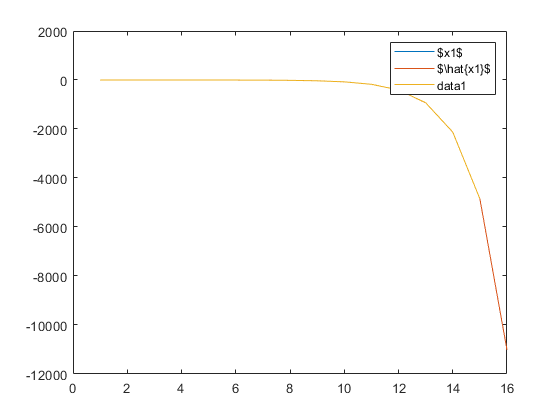

n_vec = [1:1:tf+1];
figure()
plot(n_vec,x(1,:))
hold on
plot(n_vec, xh(1,:))
legend('$x1$','$\hat{x1}$')

plot(n_vec(1:tf), xhh(1,:))

## P3

clear;
rng(69)
x = randn(1)

x = -0.5573

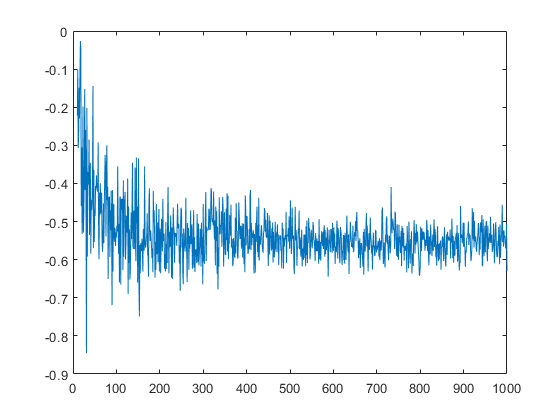


n = [10:1:1e3];
xh_vec = zeros(1,length(n));
error_vec = zeros(1,length(n));
rng('shuffle')
for i = 1:length(n)
    v = randn(1,i);
    y = x + v;
    
    xh_vec(i) = (1-(n(i))/(1+n(i)))*sum(y);
    error_vec(i) = xh_vec(i)-x;
end

figure()
plot(n, xh_vec)

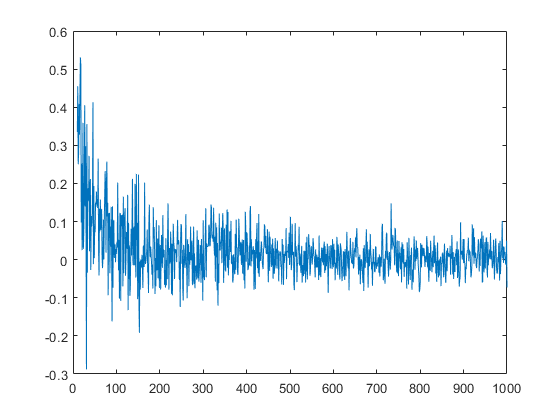

plot(n, error_vec)

syms n
simplify(1-(n-n^2/(n+1)))

$$ans = \frac{1}{n+1}$$

## P4

A = [0 1 0 0; 0 -0.2 3 0; 0 0 0 1; 0 -0.5 30 0]

A =          0    1.0000         0         0
         0   -0.2000    3.0000         0
         0         0         0    1.0000
         0   -0.5000   30.0000         0


B1 = [0;1;0;5]

B1 =      0
     1
     0
     5


B = [0 0;1/4 0;0 0;0 1/10]

B =          0         0
    0.2500         0
         0         0
         0    0.1000


C = [1 0 0 0;0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [1/4 0;0 1/20]

D =     0.2500         0
         0    0.0500


invD2 = inv(D*D');

P = are(A',C'*invD2*C,B*B')

P =     0.0792    0.0505    0.0013    0.0025
    0.0505    0.0771    0.0133    0.0668
    0.0013    0.0133    0.0273    0.1490
    0.0025    0.0668    0.1490    0.8152


L = P*C'*invD2

L =     1.2671    0.5179
    0.8081    5.3104
    0.0207   10.9191
    0.0400   59.6184


q = [1, 5, 1, 5]

q =      1     5     1     5


K = lqr(A,B1,diag(q), 0.5)

K =    -1.4142   -4.4316   18.8017    5.0905



sim('sys_noisy.slx', 30)

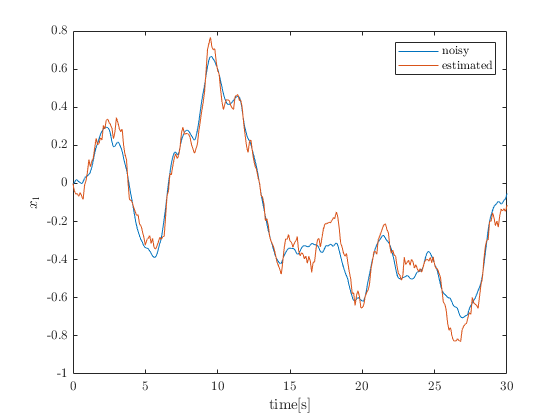

set(0, 'defaultTextInterpreter', 'latex'); 
x1 = x.Data(1,:);
x2 = x.Data(2,:);
x3 = x.Data(3,:);
x4 = x.Data(4,:);
t = x.Time;

xh1 = xh.Data(1,:);
xh2 = xh.Data(2,:);
xh3 = xh.Data(3,:);
xh4 = xh.Data(4,:);


figure
plot(t,x1)
hold on
plot(t,xh1)
xlabel('time[s]')
ylabel('$x_1$')
legend('noisy','estimated')

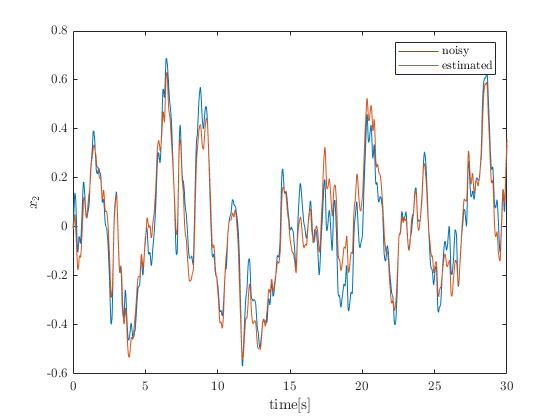


figure
plot(t,x2)
hold on
plot(t,xh2)
xlabel('time[s]')
ylabel('$x_2$')
legend('noisy','estimated')

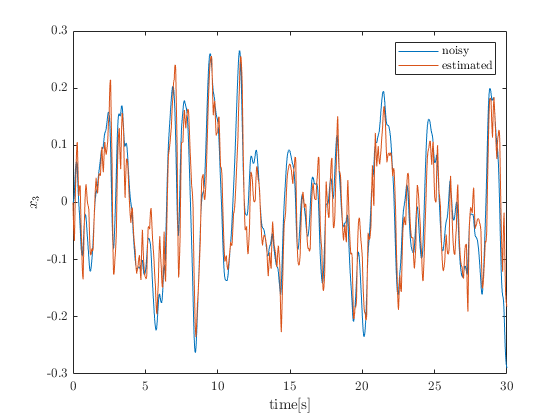


figure
plot(t,x3)
hold on
plot(t,xh3)
xlabel('time[s]')
ylabel('$x_3$')
legend('noisy','estimated')

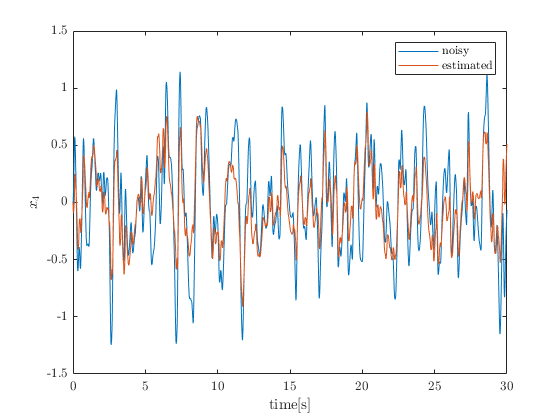


figure
plot(t,x4)
hold on
plot(t,xh4)
xlabel('time[s]')
ylabel('$x_4$')
legend('noisy','estimated')